# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Tema 3. Detección de bordes**

**  Departamento de Electrónica. Universidad de Alcalá.**

## Filtros espaciales que realzan los bordes

En el siguiente ejemplo, se aplica a la imagen de entrada un filtro que detecta los bordes horizontales, otro que detecta los verticales y finalmente se suman los dos para obtener la imagen de bordes global.

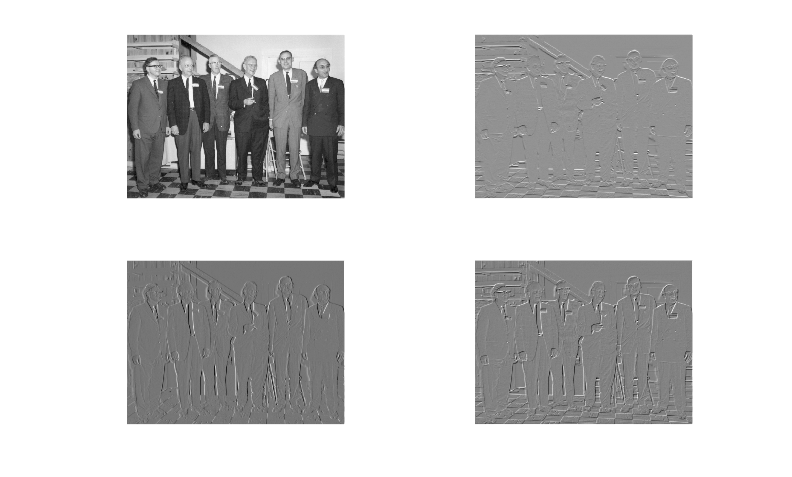

close all
clear all
clc

load gatlin; 
im=ind2gray(X,map);

h=[ 1 1 1; 0 0 0; -1 -1 -1]; %filtro detector de bordes horizontales
Y=filter2(h,im); %imagen bordes horizontales
bordes_hori=(Y-min(min(Y)))/(max(max(Y))-min(min(Y))); %imagen bordes horizont. normalizada

Y=filter2(h',im); %imagen bordes verticales pues se filtro con h' = filtro de bordes verticales
bordes_verti=(Y-min(min(Y)))/(max(max(Y))-min(min(Y))); %imagen bordes verticales normalizada

Y=bordes_hori+bordes_verti; %imagen bordes
bordes=(Y-min(min(Y)))/(max(max(Y))-min(min(Y))); %imagen bordes normalizada
figure,subplot(2,2,1),imshow(im)
subplot(2,2,2); imshow(bordes_hori);
subplot(2,2,3); imshow(bordes_verti),
subplot(2,2,4); imshow(bordes)

**Pruebe los filtros con distintas imágenes comprobando los resultados.**

## Otros filtros lineales especiales 

Algunos filtros mejoran las imágenes de manera especial. Por ejemplo, aplicando el filtro Sobel en una única dirección, se puede alcanzar un efecto de realce. La rutina *fspecial* genera varios tipos de filtros predefinidos. Después de crear un filtro con *fspecial*, se aplica a los datos de la imagen utilizando *filter2*. Este ejemplo aplica un filtro Sobel a la imagen trees. 

load trees
I=ind2gray(X,map); %Imagen de intensidad double (rango de 0 a 1)
h=fspecial('sobel') %Observe como es un filtro detector de bordes horizontales

h =      1     2     1
     0     0     0
    -1    -2    -1


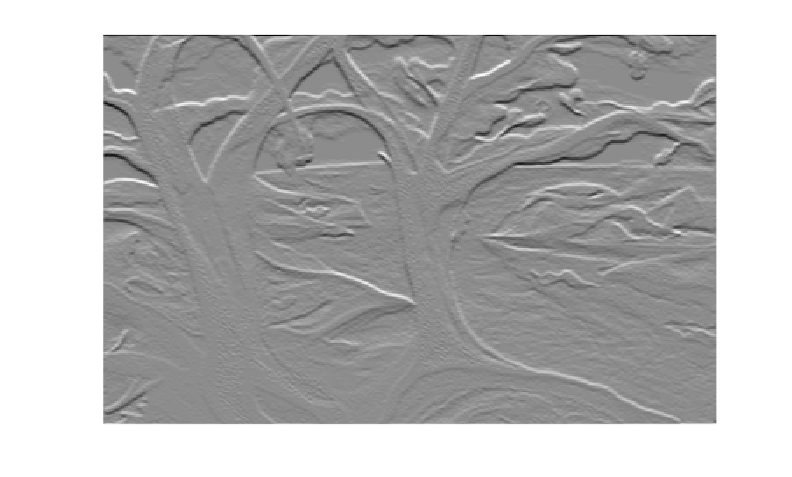

J=filter2(h,I);
figure, colormap(gray(128))
imagesc(J)
axis off

La imagen obtenida tras el filtro de Sobel contiene valores fuera del rango 0.0 a 1.0 de la imagen de partida; *imagesc* es por lo tanto la mejor elección para visualizarla, ya que hace corresponder los valores de intensidad al rango completo de salida. Otra opción es normalizar la imagen obtenida al rango 0.0 a 1.0 (double) y visualizarla entonces con *imshow*. 

Algunos **filtros** que se pueden obtener con la función fspecial son: 

- 'sobel'     for a Sobel horizontal edge-emphasizing  filter.

- 'prewitt'   for a Prewitt horizontal edge-emphasizing  filter.

- ...

**Pruebe con distintos filtros y distintas imágenes y extraiga conclusiones. **

La función *edge *proporciona un número de estimadores derivativos, cada uno de los cuales implementa una de las definiciones indicadas anteriormente. Se puede elegir entre dos métodos de detección que obtienen buenos resultados: Canny y Sobel. 

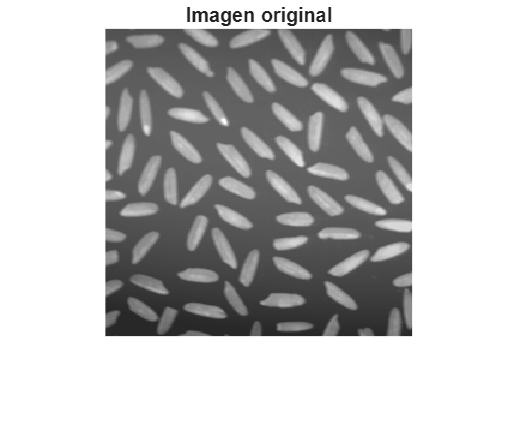

filename = 'rice.tif';  %% grayscale
%% filename = 'canoe.tif'; %% indexed 
%% filename = 'flowers.tif'; %% truecolor
info = imfinfo(filename);
if strcmp(info.ColorType,'indexed')
    [X,map] = imread(filename);
    I = ind2gray(X,map);
elseif strcmp(info.ColorType,'truecolor')
    rgb=imread(filename);
    I=rgb2gray(rgb);
else
    I=imread(filename);
end

imshow(I)

title('Imagen original');

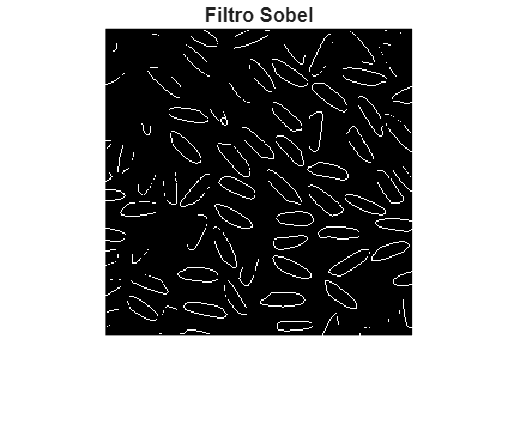

BW1 = edge(I, 'sobel');  %Imagen binaria (0 o 1) de bordes tras filtro de sobel 
BW2 = edge(I,'canny');  %Imagen binaria de bordes tras filtro de canny 
figure, imshow(BW1); title('Filtro Sobel'); 

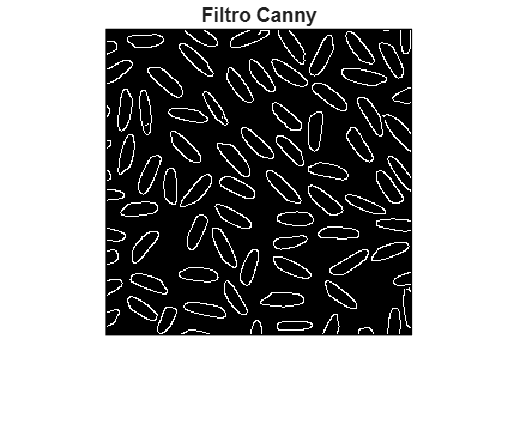

figure, imshow (BW2); title ('Filtro Canny'); 

**Pruebe los filtros con distintas imágenes comprobando los resultados.**